flights = importFlightsData("flightsJan.csv");

flights

flights = 469968×20 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    _____________________    ____________

missing = ismissing(flights)

missingcol = 559365×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


flights.SCHEDULED_DEPARTURE_HOUR = dateshift(flights.SCHEDULED_DEPARTURE_TIME,"start","hour");
flightsNotArriving = groupsummary(flights,"SCHEDULED_DEPARTURE_HOUR","sum",["DIVERTED" , "CANCELLED"]);
flightsNotArriving.Properties.VariableNames = [ "Scheduled_Departure_Hour" "Total_Flights" "Diverted_Flights" "Cancelled_Flights"]; 

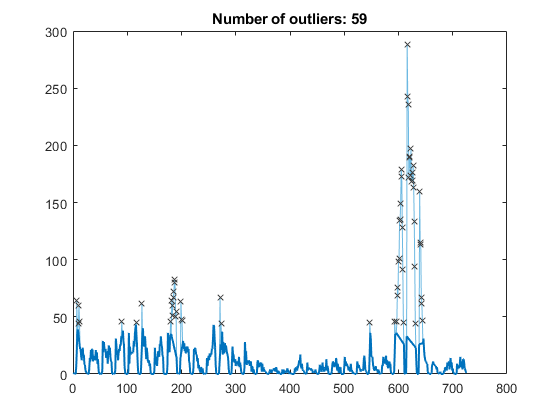

% Remove outliers
[cleanedData,outlierIndices2] = rmoutliers(flightsNotArriving.Cancelled_Flights,...
    'quartiles');

% Display results
clf
plot(flightsNotArriving.Cancelled_Flights,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on
plot(find(~outlierIndices2),cleanedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(find(outlierIndices2),flightsNotArriving.Cancelled_Flights(outlierIndices2),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices2))])


% Compute thresholds and center
[~,thresholdLow3,thresholdHigh3] = ...
    isoutlier(flightsNotArriving.Cancelled_Flights,'quartiles');

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow3*[1 1] NaN thresholdHigh3*[1 1]],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

Error using horzcat
Dimensions of arrays being concatenated are not consistent.


hold off
legend
clear thresholdLow3 thresholdHigh3

flightsNotArriving

flightsNotArriving = 725×4 table
    Scheduled_Departure_Hour    Total_Flights    Diverted_Flights    Cancelled_Flights
    ________________________    _____________    ________________    _________________

      01-Jan-2015 00:00:00            21                0                    0        
      01-Jan-2015 01:00:00            21                0                    1        
      01-Jan-2015 02:00:00             8                0                    1        
      01-Jan-2015 03:00:00             2                0                    0        
      01-Jan-2015 04:00:00             4                0                    0        
      01-Jan-2015 05:00:00           116                0                    7        
      01-Jan-2015 06:00:00           658                1                   64        
      01-Jan-2015 07:00:00           722       

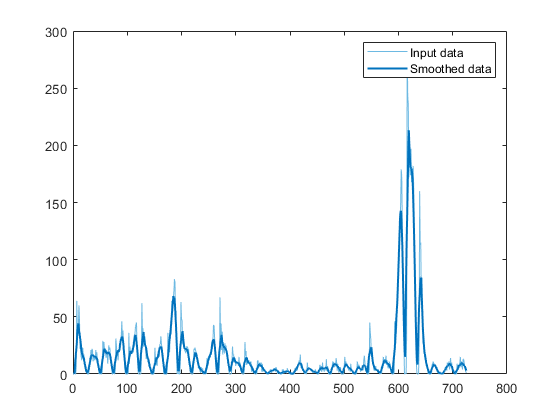

% Smooth input data
smoothedData2 = smoothdata(flightsNotArriving.Cancelled_Flights,'movmean',7);

% Display results
clf
plot(flightsNotArriving.Cancelled_Flights,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on
plot(smoothedData2,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

corrcoef(smoothedData,smoothedData2)

ans =     1.0000    0.2252
    0.2252    1.0000
